clc
clear

scale = 1024;
wheat_line_num = 31;
wheat_gap = scale/(wheat_line_num+1);
wheat_radius = wheat_gap*0.4;


framerate = 10;
time = 10;
freq = 0.3;  % 1/s
f_x = 0.05; % 1/s
f_y = 0; % 1/s
f_xy  = 0; % 1/s
tau_c = 10; % s
x_c = 500; %pixel
y_c = 500; %pixel
ifTimeDecay = 0;
ifSpaceDecay = 0;
scale = 1024;
framerate = 10;
time = 10;
freq = double(0.2);  % Frequency in Hz, s^-1
f_xy = double(0);
ifTimeDecay = 0;
ifSpaceDecay = 0;


Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 2).


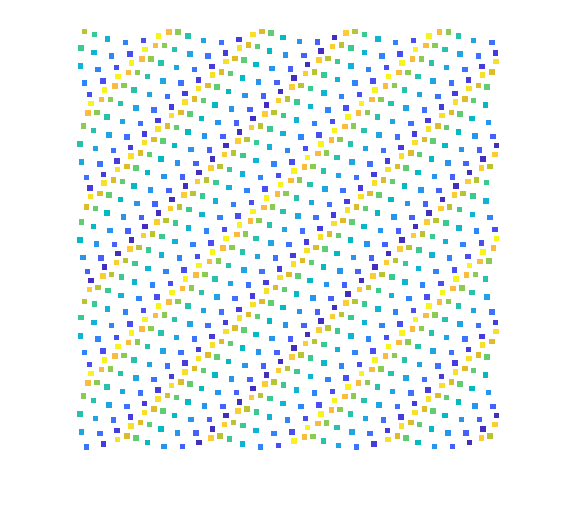

output_path='\\sf3.bss.phy.private.cam.ac.uk\cicutagroup\yz655\modelling\circle_videos\paper_videos\time_freq\';
output_path='';
dot_size = 12;
f_x = 0.15; % 1/s
f_y = 0.15; % 1/s
freq_list = [0.2 0.4 0.6];
freq_list = [0.3];

for freq=freq_list
    [phase_matrix,video_name] = make_phase_matrix(wheat_line_num, framerate,...
        time, freq, f_x, f_y, f_xy, tau_c, x_c, y_c,...
        ifTimeDecay, ifSpaceDecay);
    
    video_mat = make_video_pixel_matrix(phase_matrix, wheat_line_num, wheat_gap, wheat_radius, framerate,...
        time, scale, dot_size);
%     make_synthetic_video(video_mat, framerate, video_name, output_path);
    imshow(squeeze(video_mat(:,:,1,:)));
end

output_path='paper_videos/complex/'

output_path = 'paper_videos/complex/'


f_x = 0.1; % 1/s
f_y = 0.1; % 1/s
theta=pi/6*5;
f_x2  = double(0.2*sin(theta)); % spatial frequency x-axis pixel^-1
f_y2  = double(0.2*cos(theta));

[phase_matrix,video_name] = make_two_wave_phase_matrix(wheat_line_num, framerate,...
    time, freq, theta, f_x, f_y, f_x2, f_y2, f_xy, tau_c, x_c, y_c,...
    ifTimeDecay, ifSpaceDecay)

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 2).


phase_matrix = phase_matrix(:,:,1) =

    0.6485    0.0201   -0.6082   -1.2365   -1.8648   -2.4931   -3.1215   -3.7498   -4.3781   -5.0064   -5.6347   -6.2630   -6.8914   -7.5197   -8.1480   -8.7763   -9.4046  -10.0330  -10.6613  -11.2896  -11.9179  -12.5462  -13.1746  -13.8029  -14.4312  -15.0595  -15.6878  -16.3161  -16.9445  -17.5728  -18.2011
   -1.6965    1.1084    0.4801   -0.1482   -0.7765   -1.4049   -2.0332   -2.6615   -3.2898   -3.9181   -4.5464   -5.1748   -5.8031   -6.4314   -7.0597   -7.6880   -8.3164   -8.9447   -9.5730  -10.2013  -10.8296  -11.4580  -12.0863  -12.7146  -13.3429  -13.9712  -14.5995  -15.2279  -15.8562  -16.4845  -17.1128
   -2.3248   -2.9531    1.5684    0.9401    0.3117   -0.3166   -0.9449   -1.5732   -2.2015   -2.8299   -3.4582   -4.0865   -4.7148   -5.3431   -5.9714   -6.5998   -7.2281   -7.8564   -8.4847   -9.1130   -9.7414  -10.3697  -10.9980  -11.6263  -12.2546  -12.8829  -13.5113  -14.1396  -14.7679  -15.3962  -16.0245
   -2.9531   -3.5814   -4.209

video_name = 'theta_2.618(rad)_fx_0.1_fy_0.1_fxy_0_tauc_0_xc_0_yc_0_freq_0.3_gray'

video_name = 'two_waves'

video_name = 'two_waves'

video_mat = make_video_pixel_matrix(phase_matrix, wheat_line_num, wheat_gap, wheat_radius, framerate,...
    time, scale, dot_size);
make_synthetic_video(video_mat, framerate, video_name, output_path);

xy = [1:wheat_line_num]*wheat_gap;
[X, Y] = meshgrid(xy);

output_path='\\sf3.bss.phy.private.cam.ac.uk\cicutagroup\yz655\modelling\circle_videos\paper_videos\direction\';

scale = 1024;
framerate = 10;
time = 10;
freq = double(0.3);  % Frequency in Hz, s^-1
f_xy = double(0);
ifTimeDecay = 0;
ifSpaceDecay = 0;
dot_size = 4;

theta_list=-pi:pi/6:pi;
for theta=theta_list
    f_x  = double(0.2*sin(theta)); % spatial frequency x-axis pixel^-1
    f_y  = double(0.2*cos(theta)); % spatial frequency y-axis pixel^-1

    [phase_matrix,video_name] = make_phase_matrix(wheat_line_num, framerate,...
        time, freq, theta, f_x, f_y, f_xy, tau_c, x_c, y_c,...
        ifTimeDecay, ifSpaceDecay);
    video_mat = make_video_pixel_matrix(phase_matrix, wheat_line_num, wheat_gap, wheat_radius, framerate,...
        time, scale, dot_size);
    make_synthetic_video(video_mat, framerate, video_name, output_path);

end


output_path='';
scale = 1024;
framerate = 10;
time = 10;
freq = double(0);  % Frequency in Hz, s^-1
f_x  = double(0.1); % spatial frequency x-axis pixel^-1
f_y  = double(0.1); % spatial frequency y-axis pixel^-1
f_xy = double(0);
ifTimeDecay = 0;
ifSpaceDecay = 0;
dot_size = 4;

[phase_matrix,video_name] = make_phase_matrix(wheat_line_num, framerate,...
    time, freq, f_x, f_y, f_xy, tau_c, x_c, y_c,...
    ifTimeDecay, ifSpaceDecay);

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 12).


video_name = 'time_invariant'

video_name = 'time_invariant'

video_mat = make_video_pixel_matrix(phase_matrix, wheat_line_num, wheat_gap, wheat_radius, framerate,...
    time, scale, dot_size);
make_synthetic_video(video_mat, framerate, video_name, output_path);


output_path='pixel_videos/'

output_path = 'pixel_videos/'

scale = 1024;
framerate = 10;
time = 10;
dot_size = 4;
freq_list = double([0.2,0.4,0.6]);  % Frequency in Hz, s^-1
f_x_list  = double([0,0.02,0.05,0.1,0.2]); % spatial frequency x-axis pixel^-1
f_y_list  = double([0,0.02,0.05,0.1,0.2]); % spatial frequency y-axis pixel^-1
f_xy_list = double(0);
ifTimeDecay = 0;
ifSpaceDecay = 0;

for freq=freq_list
    for f_x=f_x_list
        for f_y=f_y_list
            [phase_matrix,video_name] = make_phase_matrix(wheat_line_num, framerate,...
                time, freq, theta, f_x, f_y, f_xy, tau_c, x_c, y_c,...
                ifTimeDecay, ifSpaceDecay);
            video_mat = make_video_pixel_matrix(phase_matrix, wheat_line_num, wheat_gap, wheat_radius, framerate,...
                time, scale, dot_size);
            make_synthetic_video(video_mat, framerate, video_name, output_path);

        end
    end
end

% Add this function to map the phase to an RGB value

function rgb_color = phase_to_rgb_color(phase)
    cmap = parula(256); % Use the jet colormap, or any other colormap you prefer
    index = round(mod(phase / (2 * pi), 1) * 255) + 1; % Map the phase value to a valid colormap index
    rgb_color = cmap(index, :);
end


function frame=plot_dot(frame,dot_x,dot_y,dot_size,rgb_color)
    half_dot_size=round(dot_size/2);
    frame(dot_y-half_dot_size:dot_y+half_dot_size,dot_x-half_dot_size:dot_x+half_dot_size,1)=rgb_color(1);
    frame(dot_y-half_dot_size:dot_y+half_dot_size,dot_x-half_dot_size:dot_x+half_dot_size,2)=rgb_color(2);
    frame(dot_y-half_dot_size:dot_y+half_dot_size,dot_x-half_dot_size:dot_x+half_dot_size,3)=rgb_color(3);
end

function [phase_matrix,video_name] = make_phase_matrix(wheat_line_num, framerate,...
    time, freq, f_x, f_y, f_xy, tau_c, x_c, y_c,...
    ifTimeDecay, ifSpaceDecay)

    time_step = 1/framerate;
    frame_num = int8(time/time_step);
    frame_c = double(tau_c/time_step);
    phase_matrix = zeros([wheat_line_num,wheat_line_num,frame_num]);
    parfor t = 1:frame_num
        for j = 1:wheat_line_num
            for i = 1:wheat_line_num
                phase_matrix(i,j,t)=exp(-ifSpaceDecay*j/x_c-ifSpaceDecay*i/y_c-ifTimeDecay*double(t)/frame_c)*(2*pi*freq*time_step*double(t)-2*pi*f_x*j-2*pi*f_y*i+2*pi*f_xy*i*j);
            end    
        end
    end

    [x_c,y_c,tau_c] = deal(ifSpaceDecay*x_c,ifSpaceDecay*y_c, ifTimeDecay*tau_c);
%     video_name = ['theta_' num2str(theta) '(rad)_fx_' num2str(f_x,3) '_fy_' num2str(f_y,3) ...
%         '_fxy_' num2str(f_xy,5) '_tauc_' num2str(tau_c) ...
%         '_xc_' num2str(x_c) '_yc_' num2str(y_c) '_freq_' ...
%         num2str(freq) '_gray'];
    video_name = ['fx_' num2str(f_x,3) '_fy_' num2str(f_y,3) ...
        '_fxy_' num2str(f_xy,5) '_tauc_' num2str(tau_c) ...
        '_xc_' num2str(x_c) '_yc_' num2str(y_c) '_freq_' ...
        num2str(freq) '_gray'];
end

function [phase_matrix,video_name] = make_two_wave_phase_matrix(wheat_line_num, framerate,...
    time, freq, theta, f_x, f_y, f_x2, f_y2, f_xy, tau_c, x_c, y_c,...
    ifTimeDecay, ifSpaceDecay)

    time_step = 1/framerate;
    frame_num = int8(time/time_step);
    frame_c = double(tau_c/time_step);
    phase_matrix = zeros([wheat_line_num,wheat_line_num,frame_num]);
    parfor t = 1:frame_num
        for j = 1:wheat_line_num
            for i = 1:wheat_line_num
                if i>j
                    phase_matrix(i,j,t)=exp(-ifSpaceDecay*j/x_c-ifSpaceDecay*i/y_c-ifTimeDecay*double(t)/frame_c)*(2*pi*freq*time_step*double(t)-2*pi*f_x*j-2*pi*f_y*i+2*pi*f_xy*i*j);
                else
                    phase_matrix(i,j,t)=exp(-ifSpaceDecay*j/x_c-ifSpaceDecay*i/y_c-ifTimeDecay*double(t)/frame_c)*(2*pi*freq*time_step*double(t)-2*pi*f_x2*j-2*pi*f_y2*i+2*pi*f_xy*i*j);
                end
            end    
        end
    end

    [x_c,y_c,tau_c] = deal(ifSpaceDecay*x_c,ifSpaceDecay*y_c, ifTimeDecay*tau_c);
    video_name = ['theta_' num2str(theta) '(rad)_fx_' num2str(f_x,3) '_fy_' num2str(f_y,3) ...
        '_fxy_' num2str(f_xy,5) '_tauc_' num2str(tau_c) ...
        '_xc_' num2str(x_c) '_yc_' num2str(y_c) '_freq_' ...
        num2str(freq) '_gray'];
end

function video_mat = make_video_pixel_matrix(phase_matrix, wheat_line_num, wheat_gap, wheat_radius, framerate,...
    time, scale, dot_size)

    time_step = 1/framerate;
    frame_num = int8(time/time_step);

    % make frame pixel matrix
    video_mat=ones(scale,scale,frame_num,3);
    
    for t=1:frame_num
        frame=255*ones(scale,scale,3);
        current_phase_matrix=phase_matrix(:,:,t);
        x_offset = round(wheat_radius*cos(current_phase_matrix));
        y_offset = round(wheat_radius*sin(current_phase_matrix));
    
        for j = 1:wheat_line_num
            for i = 1:wheat_line_num
                dot_x=j*wheat_gap+x_offset(i,j);
                dot_y=i*wheat_gap+y_offset(i,j);
                rgb_color=phase_to_rgb_color(current_phase_matrix(i,j));
                frame=plot_dot(frame,dot_x,dot_y,dot_size,rgb_color);
            end
        end
        
        video_mat(:,:,t,:)=frame;
    end

end

function [] = make_synthetic_video(video_mat, framerate, video_name, output_path)
    output = [output_path 'large_' video_name];
    VidObj = VideoWriter(output, 'MPEG-4'); %set your file name and video compression
 
%     VidObj = VideoWriter('movie.avi', 'Uncompressed AVI'); %set your file name and video compression
    VidObj.FrameRate = 10; %set your frame rate
    open(VidObj);
    for f = 1:size(video_mat, 3)  
        writeVideo(VidObj,mat2gray(video_mat(:,:,f)));
    end
    close(VidObj);
end